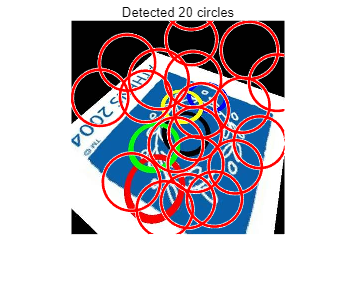

% 1. 读取图像并检测圆
img = imread('olympic.jpg');
[centers, radii] = myFindCircles(img, 50, 60, 'EdgeThreshold', [0.1, 0.25]);

% 2. 可视化结果
figure;
imshow(img); hold on;
viscircles(centers, radii, 'Color', 'r');
title(sprintf('Detected %d circles', size(centers,1)));